
$$y_{k+1}=y_k+hf(x_k,y_k)$$


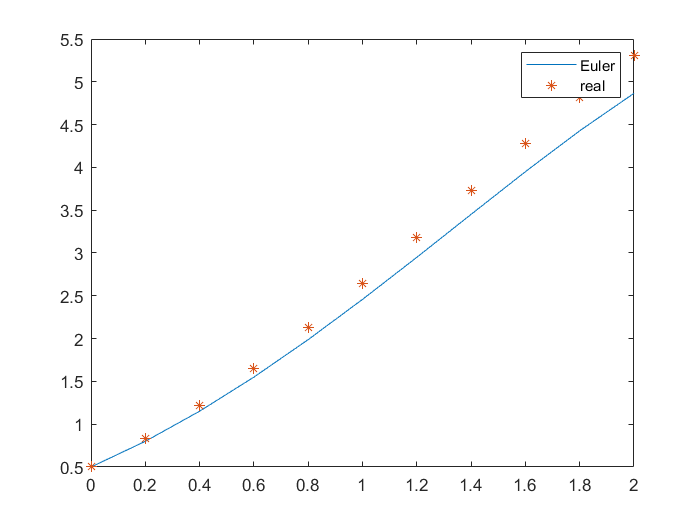

clc,clear,close all
f = @(x,y) y-x^2+1;             % 设置微分方程
a = 0;                          % 区间左端点
b = 2;                          % 区间右端点
h = 0.2;                        % 取点间隔
x = a:h:b;                      % x_i
n = length(x)-1;                % n
y = zeros(1,n+1);               % 预分配内存
y(1) = 0.5;                     % 设置初始值

for i = 1:length(x)-1
    delta = f(x(i),y(i));
    y(i+1) = y(i)+delta*h;
end

plot(x,y)

% 这里的函数 f 是题目函数 y 的解析解
% 将 x_i 带入解析解中并作图验证求解是否准确
f = @(x) 2*x-exp(x)/2+x.^2+1;
y_real = f(x);
hold on
plot(x,y_real,'*')
xlim([a,b])
legend('Euler','real')